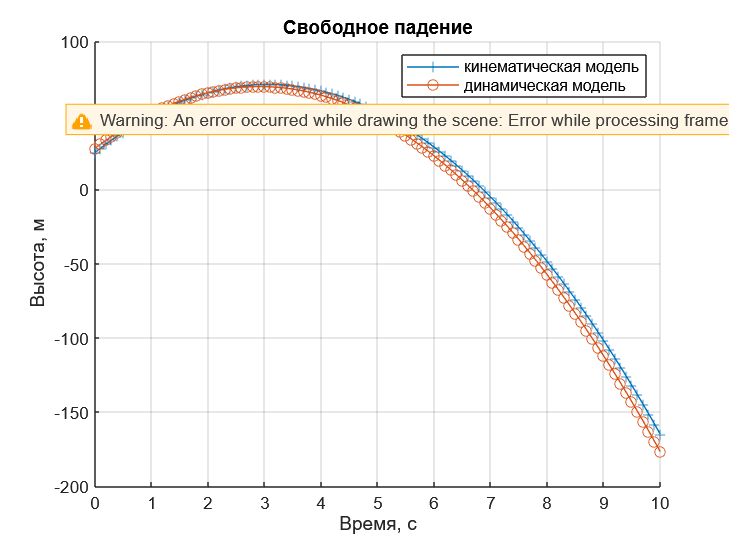

g = 9.8;
v0 = 30;
y0 = 25;
dt = 0.1;
t = 0:dt:10;
f=figure();
y1 = y0 + v0*t - g*t.^2/2;
hold all
%scatter(t,y, Marker='.', DisplayName='кинематическая модель')
plot(t,y1, DisplayName='кинематическая модель', Marker="+")
title('Свободное падение')
xlabel('Время, с')
ylabel('Высота, м')
grid on






g_vec = repmat(g, length(t),1);
v = v0 - cumsum(g_vec*dt);
y2 = y0 + cumsum(v*dt);
%scatter(t,y, Marker='.', DisplayName='динамическая модель')
plot(t,y2, DisplayName='динамическая модель', Marker="o")
legend


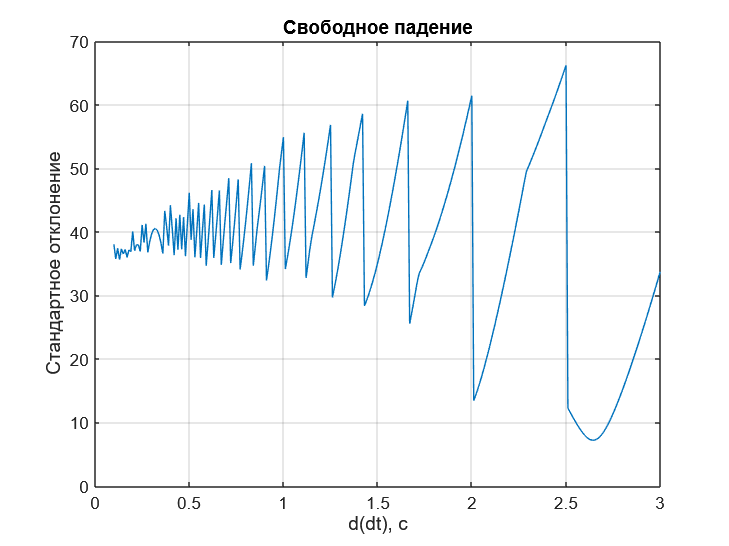

dev = std(abs(y1), abs(y2)) ;
ddt = 0.01;
dev = 0.1:ddt:3;
f1 = figure();

i=1;
for dt=0.1:ddt:3
    t = 0:dt:10;
    y1 = y0 + v0*t - g*t.^2/2;
    g_vec = repmat(g, length(t),1);
    v = v0 - cumsum(g_vec*dt);
    y2 = y0 + cumsum(v*dt);
    dev(i)=std(abs(y1), abs(y2));
    i=i+1;
end

dt = 0.1:ddt:3;
plot(dt,dev)
grid on
xlabel('d(dt), с')
ylabel('Стандартное отклонение')
title('Свободное падение')

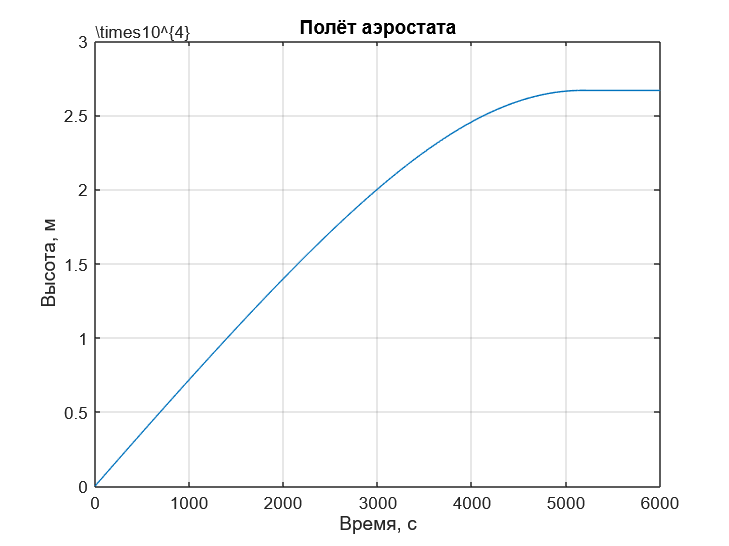

dt = 0.02;
m = 0.2;
rho0=1;
r = 1;
t = 0:dt:6000;

y = zeros(size(t));
y(1) = 0;
v=zeros(size(t));
v(1) = 0;
rho1 = 1;
g=9.8;
V = 4/3 * pi * r^3;
k = 0.5 * 0.47 * 3.14 * r.^2;

for i = 1:length(t)-1
    
    F_A = g * V * density(y(i));
    F_resist = k * density(y(i)) * (abs(v(i)))^2 * sign(v(i));
    F_grav = m * g;
    v(i+1) = v(i) + (F_A - F_resist - F_grav) / m * dt;
    y(i+1) = y(i) + v(i+1) * dt;
end
f = figure();

plot(t, y)
xlabel('Время, с')
ylabel('Высота, м')
title('Полёт аэростата')
grid on

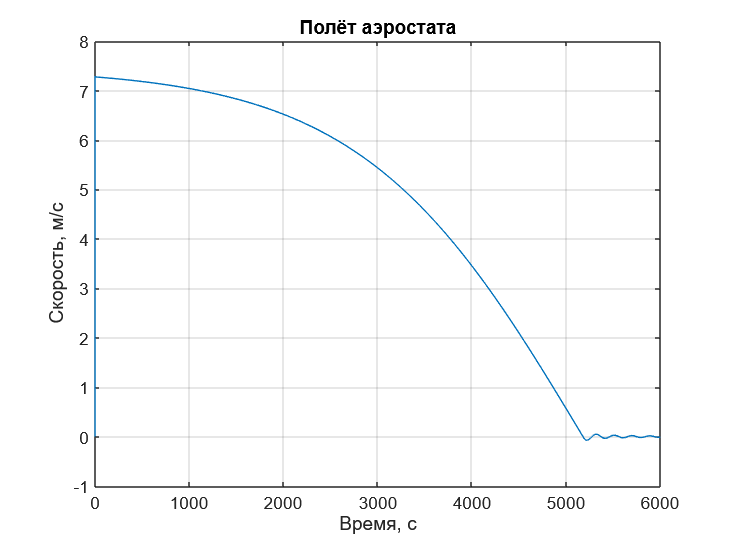


f = figure();

plot(t, v)
xlabel('Время, с')
ylabel('Скорость, м/с')
title('Полёт аэростата')
grid on

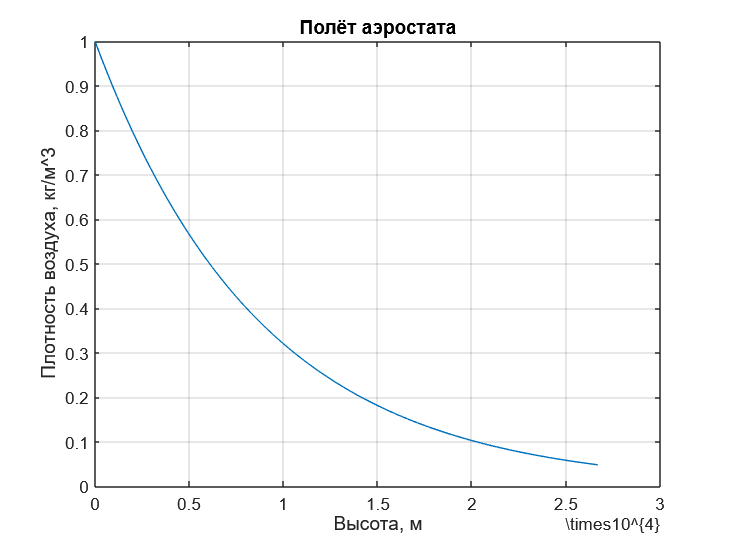


f = figure();


plot(y, density(y))
grid on
xlabel('Высота, м')
ylabel('Плотность воздуха, кг/м^3')
title('Полёт аэростата')